clear
close all

x = sym('x','real');
f(x) = x^2;
g = sym(0);
h = sym(0);
m = sym(1);
q = sym(-1);
E = sym(1);
I = sym(1);

% Exact solution
exactSolution = computeExactSolution(E,I,f,g,h,m,q);
figure
hold on
fplot(exactSolution.U,exactSolution.domain)

% FE Solution

nELEM = 4

nELEM = 4

eDegree = 2

eDegree = 2

elemContinuity = [-1 1 1 1 -1]

elemContinuity =     -1     1     1     1    -1



feSolution = main(nELEM,eDegree,elemContinuity,f,g,h,m,q,E*I);

$$JAC(x) = 8$$

$$JAC(x) = 8$$

$$JAC(x) = 8$$

$$JAC(x) = 8$$

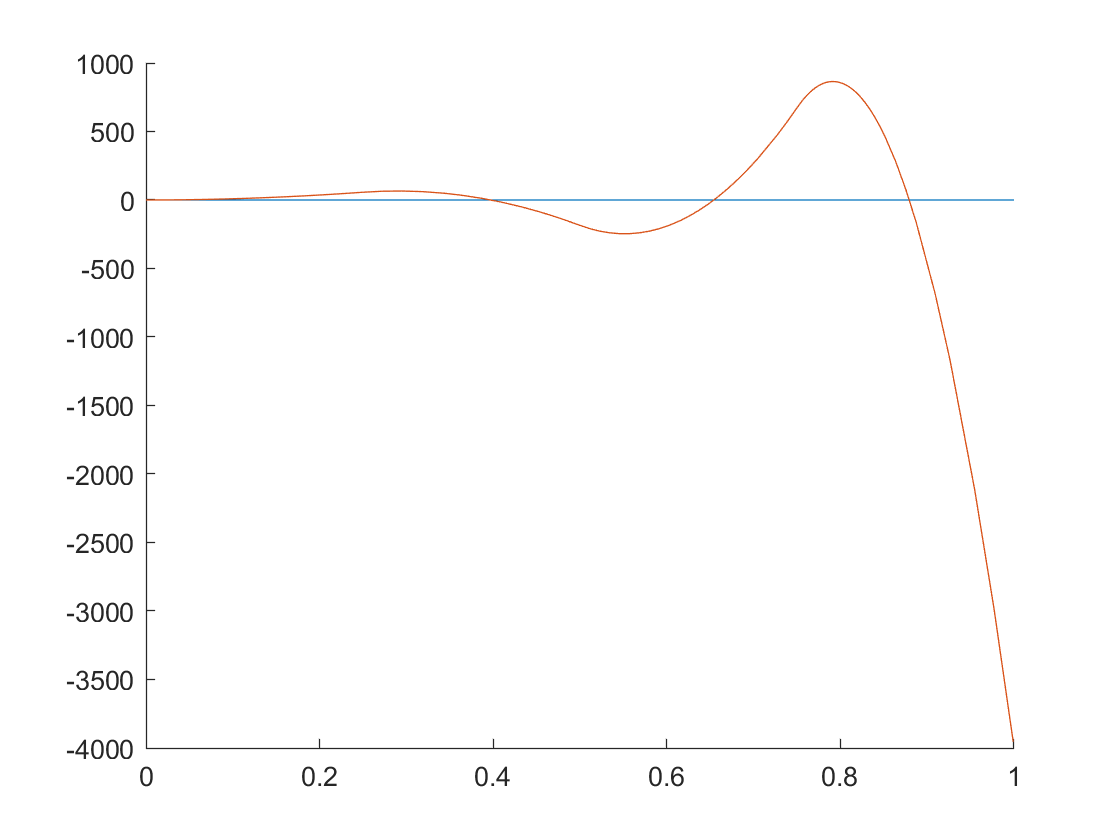

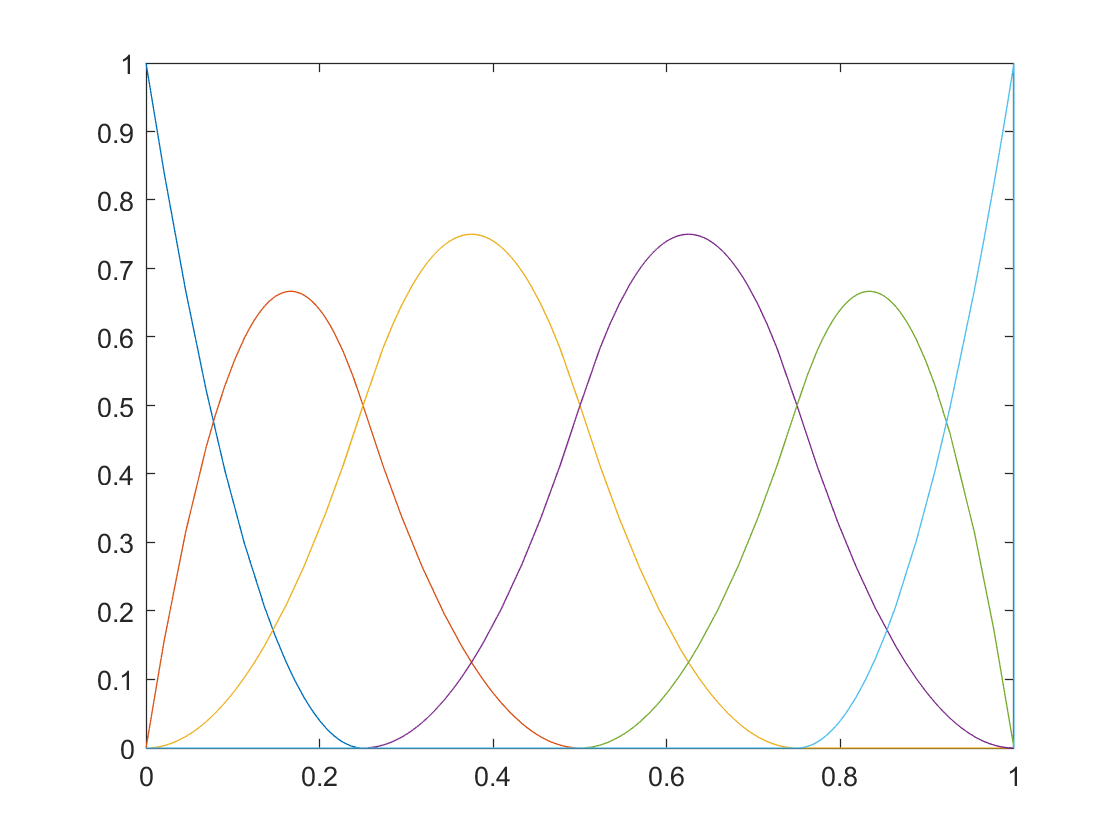

fplot(feSolution.U,exactSolution.domain)
drawnow

figure
fplot(feSolution.Spline.basis.functions,exactSolution.domain)
drawnow

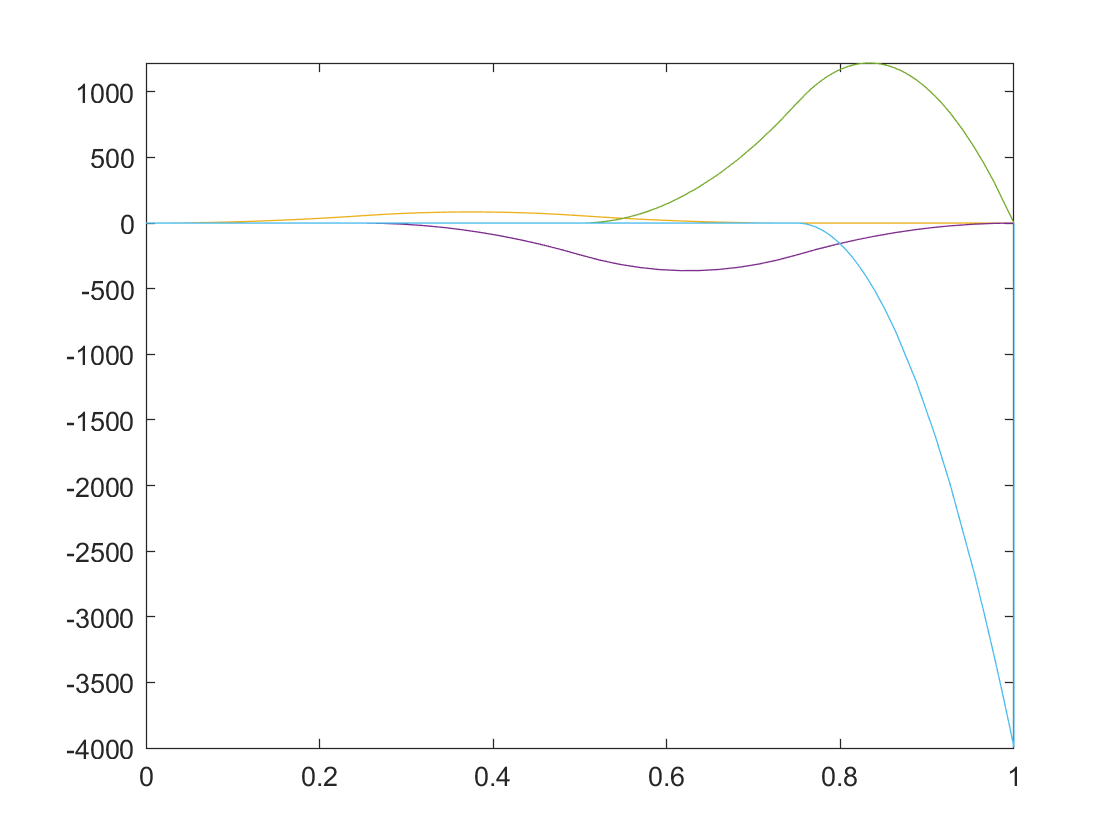

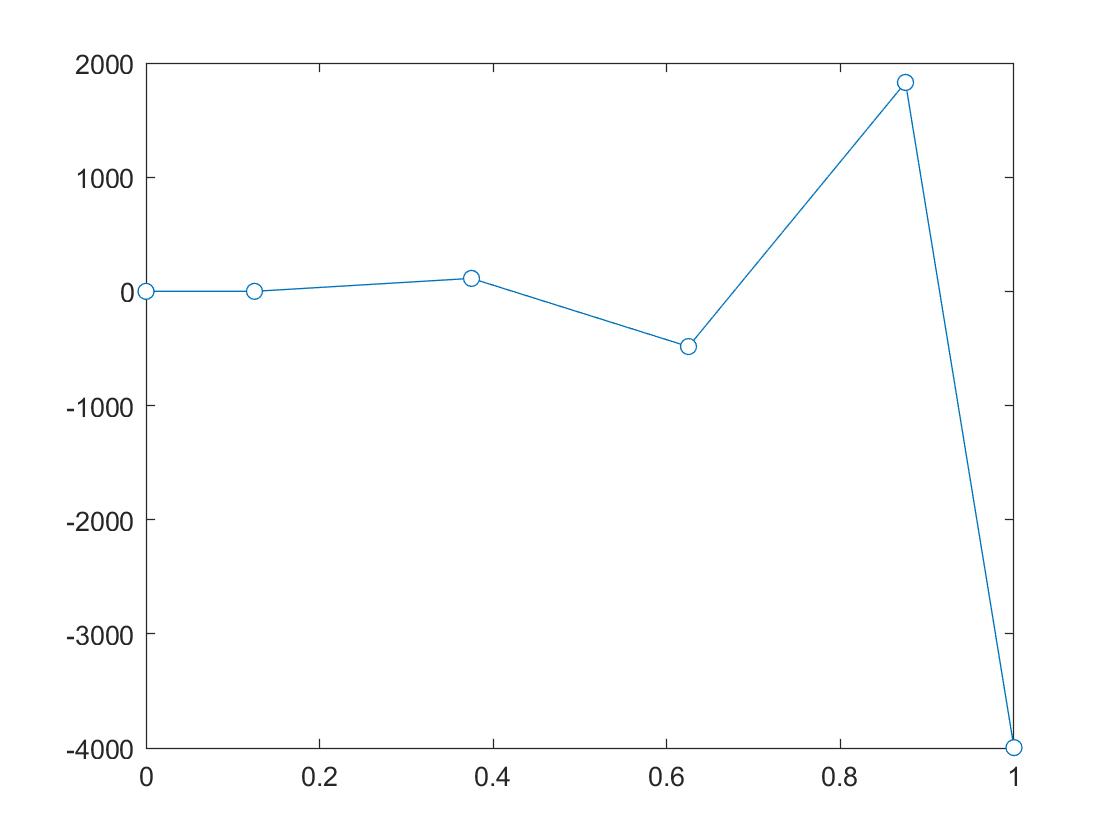


figure
fplot(feSolution.Spline.basis.functions .* feSolution.LinearSystem.d,exactSolution.domain)
drawnow

figure 
plot(feSolution.Spline.nodes', feSolution.LinearSystem.d','-o','MarkerFaceColor',"auto")
drawnow